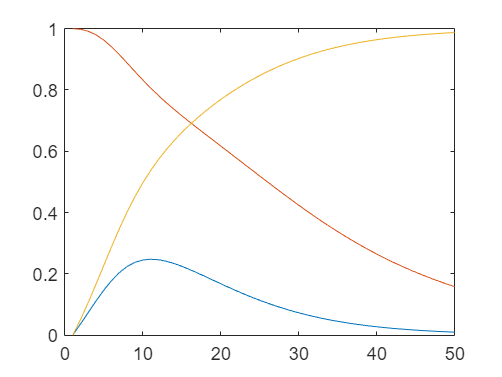

x = [0,1,0]';

d = 0.05;
c = 0.3;
s = 0.50;

P1 = [
    [1, 1/2, 0];
    [1/2, 1/4, 0];
    [0, 0, 0]
];

P2 = [
    [0, 1/2, 1];
    [1/2, 1/2, 1/2];
    [1, 1/2, 0]
];

P3 = [
    [0, 0, 0];
    [0, 1/4, 1/2];
    [0, 1/2, 1]
];

N = 50;
recs = zeros(3, N);
recs(:, 1) = x;
for i = 2 : N
    u = c * s * x' * P1 * x + (1 - d) * x(1);
    v = c * s * x' * P2 * x + (1 - d) * x(2);
    w = 1.4 * c * s * x' * P3 * x + (1 - d) * x(3);
    x = [u, v, w]';
    x = x / norm(x);
    recs(:, i) = x;
end
figure;
plot(1 : N, recs(1, :))
hold on
plot(1 : N, recs(2, :))
plot(1 : N, recs(3, :))
hold off

ffplot

Unrecognized function or variable 'using'.